clear; clc; close all;

%% ---------------- 1. READ PARAMETERS FROM CSV --------------------------
params = readtable("Key_Param_recording.csv", 'ReadRowNames', true);

W_0                = params{"W_0_guess","Value"};
W_e                = params{"W_e","Value"};
W_f                = params{"W_f","Value"};
W_crew   = params{"W_crew","Value"};
W_pax   = 14850;
W_cargo   = params{"W_cargo","Value"};
%% ---------------- 2. PIE CHART OF WEIGHT BREAKDOWN ----------------------
values = [W_e, W_f, W_crew, W_pax, W_cargo];
labels = {'Empty weight', 'Fuel', 'Crew', 'Passengers', 'Cargo'};

% Colours from your phase palette (colour-blind friendly, varied lightness)
pieColors = [0.000 0.243 0.455;   % Empty weight - Imperial blue
             0.520 0.745 0.890;  
             0.760 0.760 0.760;
             0.980 0.850 0.450;  
             0.600 0.250 0.000   % Passengers   - dark brown
             ];  % Cargo        - light grey

% Check the parts add up to the total
fprintf('Sum of parts: %.1f kg\n', sum(values));

Sum of parts: 286601.3 kg


fprintf('W_0 guess:    %.1f kg\n', W_0);

W_0 guess:    286601.3 kg


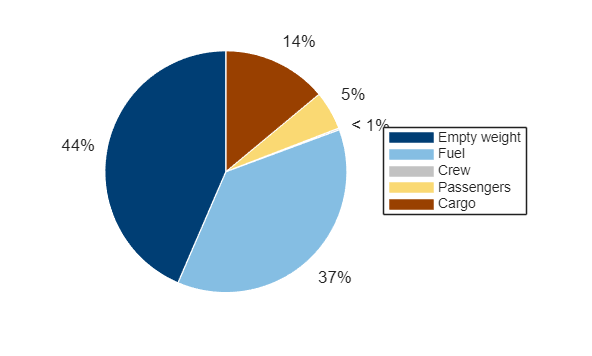


figure('Color', 'w');
p = pie(values);

% pie() returns a patch and a text label for each slice, in that order
for k = 1:numel(values)
    p(2*k-1).FaceColor = pieColors(k,:);
    p(2*k-1).EdgeColor = 'w';
    p(2*k).FontSize = 11;
end

legend(labels, 'Location', 'eastoutside');